EP3 = 1:1:100;  NO = 1:1:100;  N_Ch = 1:1:100;
alpha = 0.5;kaff = alpha*EP3+(1-alpha)*NO;
hc_aff = 20;EC50_Aff = 40;EC50_Ch = 25;

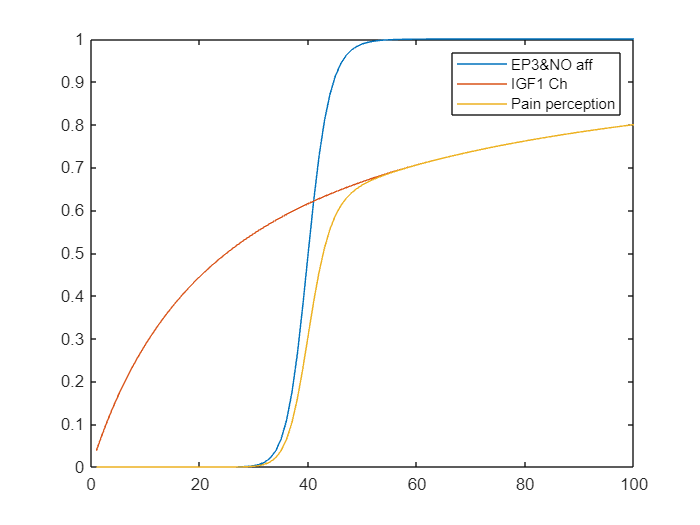

sigmoid1 = 1*(kaff.^hc_aff)./(kaff.^hc_aff + EC50_Aff^hc_aff);
sigmoid2 = 1* N_Ch./(N_Ch + EC50_Ch);
sigmoid = sigmoid1.* sigmoid2;

vars ={'EP3&NO aff', 'IGF1 Ch', 'Pain perception'};
plot(sigmoid1);hold on;
plot(sigmoid2);hold on;
plot(sigmoid);
legend(vars);